clear clc
syms vin vout s c r w H denHreal denH numH positive

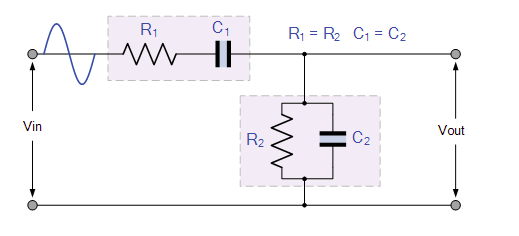

# Impedancia de entrada do bloco RC

Primeiro é feito a simplificação da assossiação paralelo

zinRC = paraleloSym(r, 1/(s*c))

$$zinRC = \frac{1}{c\,s+\frac{1}{r}}$$

Em seguida, soma-se o resultado com a associação serie R + C

zinRC = zinRC + r + 1/(s*c)

$$zinRC = r+\frac{1}{c\,s+\frac{1}{r}}+\frac{1}{c\,s}$$

Voltamos ao domínio do tempo

s = 1i*w;
zinRC = subs(zinRC);

Simplificamos os resultados e obtemos a impedância de entrada final:

zinRC = simplify(zinRC)

$$zinRC = -\frac{-c^{2}\,r^{2}\,w^{2}+3\,c\,r\,w\,\mathrm{i}+1}{c\,w\,\left(c\,r\,w-\mathrm{i}\right)}$$

Desfazendo a redefinição de s para o próximo cálculo

syms s

# Impedancia de saida do bloco RC

Primeiro soma-se o elemento serie R+C

zoutRC = r + 1/(s*c)

$$zoutRC = r+\frac{1}{c\,s}$$

Em seguida  é feito o paralelo deste com o resto do circuito, que é a associação paralela R//C

zoutRC = paraleloSym(zoutRC, r,1/(s*c))

$$zoutRC = \frac{1}{\frac{1}{r+\frac{1}{c\,s}}+c\,s+\frac{1}{r}}$$

Voltamos ao domínio do tempo:

s = 1i*w;
zoutRC = subs(zoutRC);

Simplificamos os resultados e obtemos a impedancia de saída final:

zoutRC = simplify(zoutRC)

$$zoutRC = \frac{r\,\left(c\,r\,w-\mathrm{i}\right)}{c^{2}\,r^{2}\,w^{2}\,\mathrm{i}+3\,c\,r\,w-\mathrm{i}}$$